# Estimation, Filtering and Detection

## Homework 1B: Forgetting methods

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

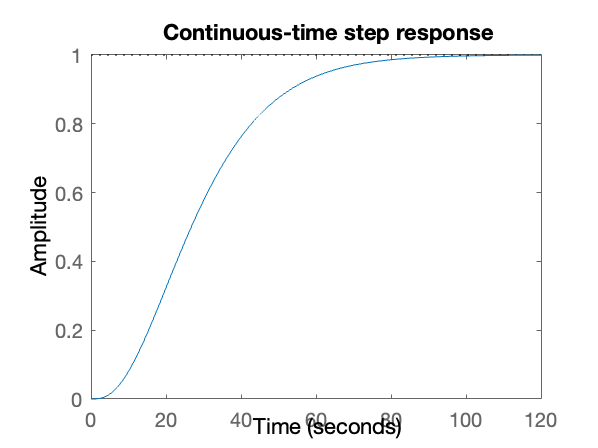

% Y(s) = 1/(1+s*tau)ˆ3*U(s)
% Find discrete time model
% Show dependancy of a(d) and b(d) parameters on
% time constant tau
Ts = 1;
% Assume ARX model structure


% Plan:
% Create transfer function
% Convert continuous state space to discrete
% implement ARX model
% show dependency of a and b on tau

time = 1000;
T = 0:Ts:time-1;
T_all = 0:Ts:3*time-1;
% Solution
% Continuous-time system
tau = 10;
sys = tf(1,[tau^3 3*tau^2 3*tau 1]);
figure(1);
step(sys);
title("Continuous-time step response");

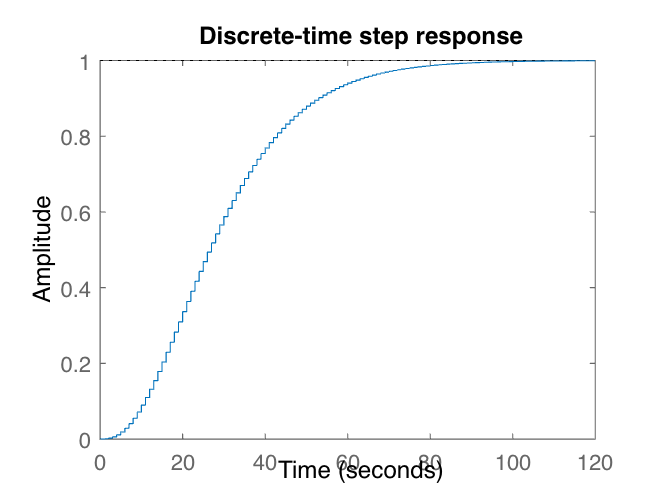


% Discrete-time system
dsys = c2d(sys,Ts,'tustin'); % using bilinear approximation 
[response,t] = step(dsys,T);
figure(2);
step(dsys);
title("Discrete-time step response");

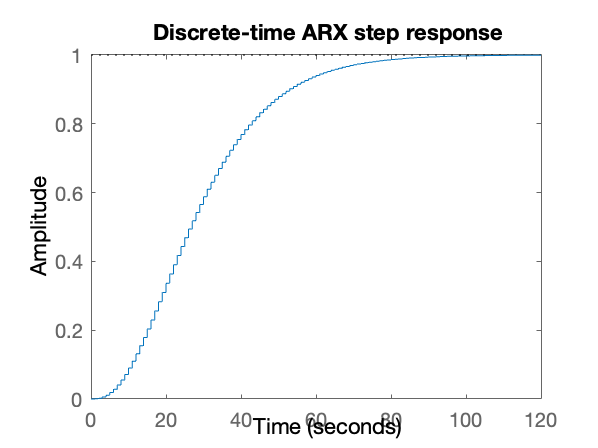


% Discrete-time system ARX
% syms z tau
% b = expand((z+1)*(z+1)*(z+1))
% a = expand((z+1+2*tau*(z-1))*(z+1+2*tau*(z-1))*(z+1+2*tau*(z-1)))

% b = z^3 + 3*z^2 + 3*z + 1
% a = 8*tau^3*z^3 - 24*tau^3*z^2 + 24*tau^3*z - 8*tau^3 + 12*tau^2*z^3 - 12*tau^2*z^2 - 12*tau^2*z + 12*tau^2 + 6*tau*z^3 + 6*tau*z^2 - 6*tau*z - 6*tau + z^3 + 3*z^2 + 3*z + 1

tau = 10;
b = [1 3 3 1];
a = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)];
dsysARX = tf(b,a,Ts,'Variable','z^-1');
figure(3);
step(dsysARX);
title("Discrete-time ARX step response");

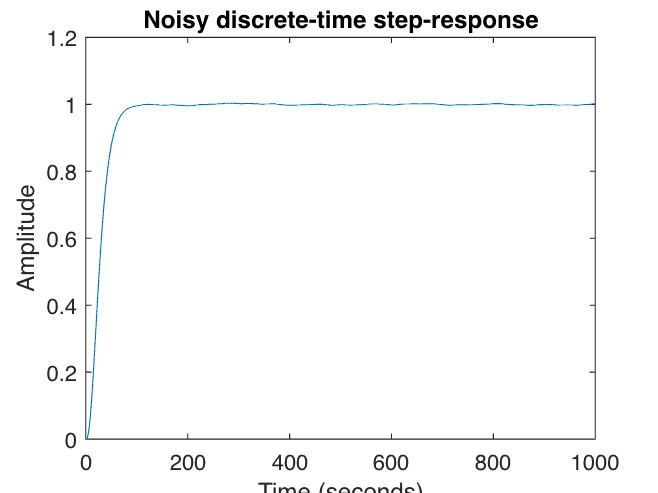


% Noisy discrete-time system
He = tf(1, a, Ts,'Variable','z^-1');  
step_input = ones(time,1);

variance = 0.01;
response = lsim(dsysARX,step_input,T);
noisevec = lsim(He,sqrt(variance)*randn(time,1),T);
y = response + noisevec;
figure(3);
plot(t,y);
title("Noisy discrete-time step-response");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 2:

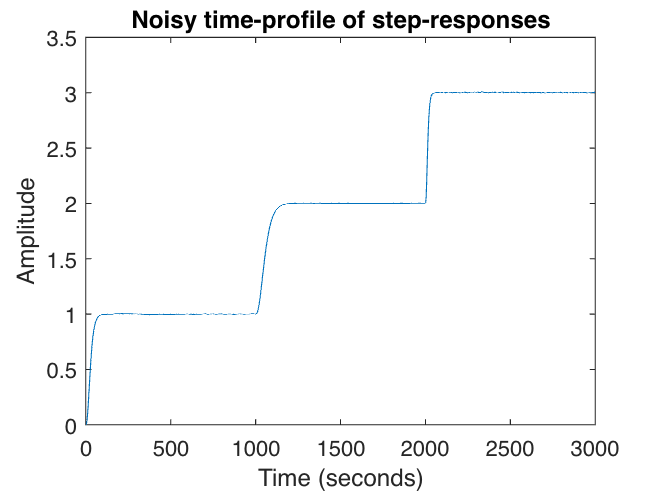


% Consider time profile

% Plan:
% Plot model from 0 to 3000 with constant tau1
% Implement if statements that change tau for each of the periods
% Plot the profile
% Do not forget the noise

% Solution
input = ones(time,1);       % step signal
time_profile = computeTimeProfile(input,Ts);
figure(4);
grid on;
plot(T_all',time_profile);  % time-profile
title("Noisy time-profile of step-responses");
ylabel("Amplitude");
xlabel("Time (seconds)");

## Problem 3:

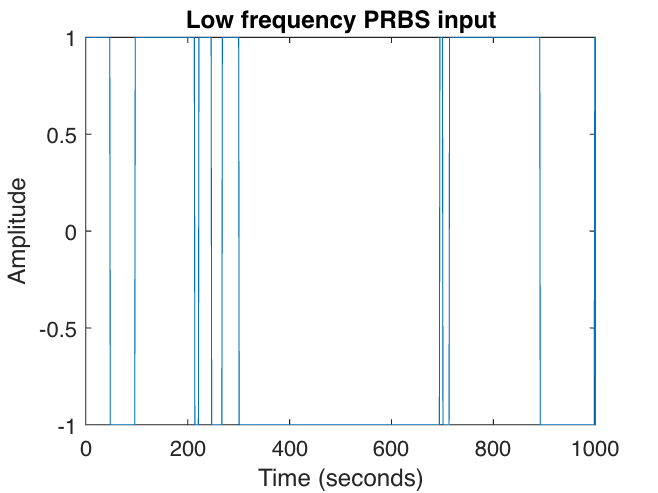

% Generate input-output data
% Use excitation signals
% Pseudo-binary sequence with 
% low frequency, white noise, high frequency
% Select the signal

% Plan:
% Find implementation of pseudo-binary signals from class materials
% Implement 3 signals 
% Generate input data and simulate the system
% Plot graphs
% Justify selection


% input sequence - low frequency input
p_switch = 0.01;
UU_low = createSignal(p_switch,time);
figure(5);
plot(T',UU_low);
title("Low frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

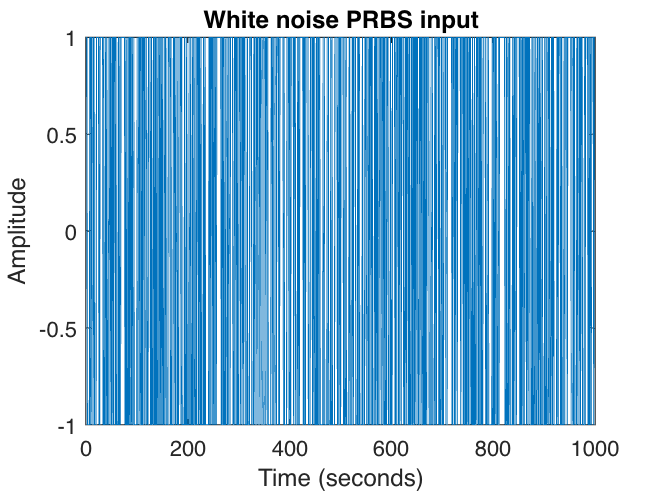


% input sequence - white noise input
p_switch = 0.5; 
UU_white = createSignal(p_switch,time);
plot(T',UU_white);
title("White noise PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)");

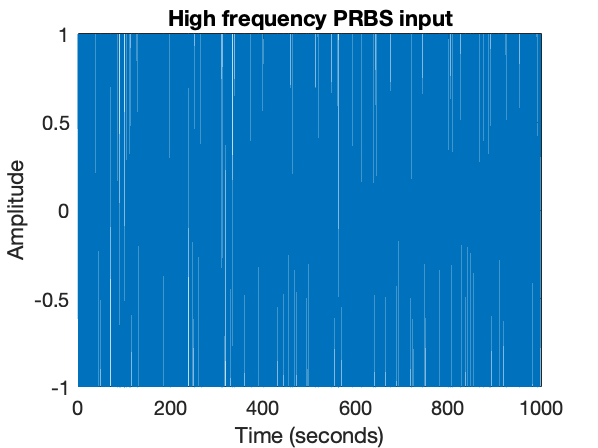


% input sequence - high frequency input 
p_switch = 0.9; 
UU_high = createSignal(p_switch,time);
plot(T',UU_high);
title("High frequency PRBS input");
ylabel("Amplitude");
xlabel("Time (seconds)"); 

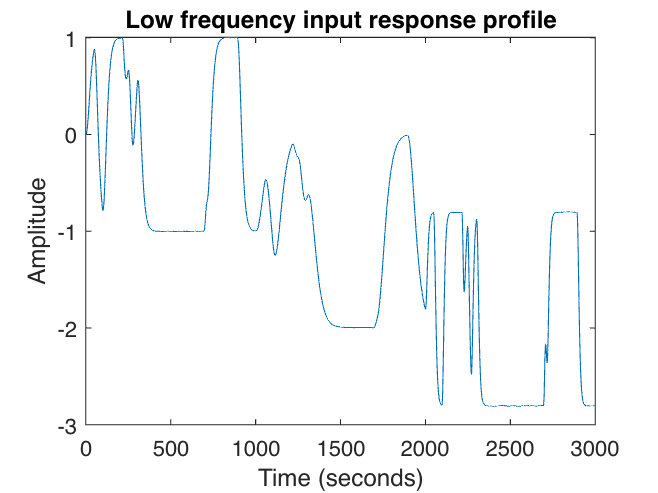


input = UU_low;      % low-frequency signal
time_profile_low = computeTimeProfile(input,Ts);
figure(6);
plot(T_all',time_profile_low); 
title("Low frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

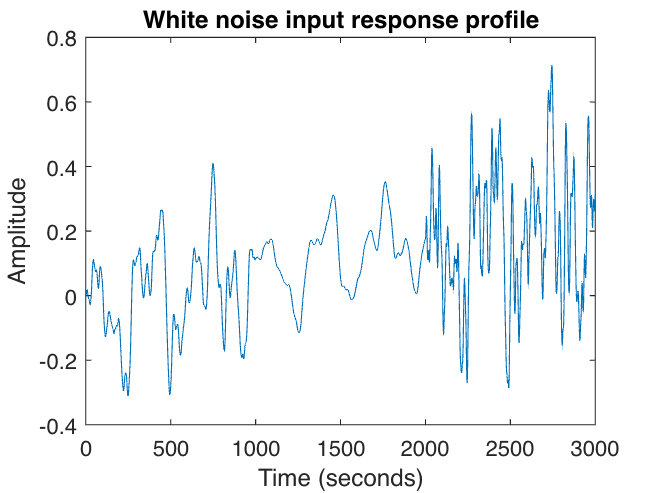


input = UU_white;      % white-noise signal
time_profile_white = computeTimeProfile(input,Ts);
figure(7);
plot(T_all',time_profile_white);
title("White noise input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");

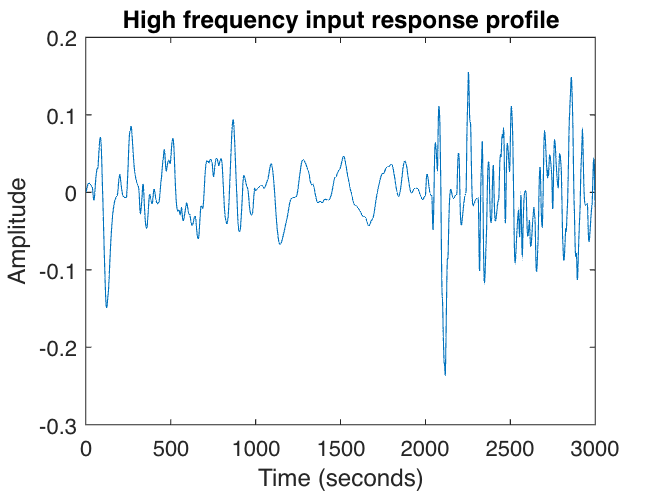


input = UU_high;      % high-frequency signal
time_profile_high = computeTimeProfile(input,Ts);
figure(8);
plot(T_all',time_profile_high); 
title("High frequency input response profile");
ylabel("Amplitude");
xlabel("Time (seconds)");


% Conclusion
% Because white-noise and high-frequency input signal
% do not show clearly dynamical changes
% the low-frequency input signal has been chosen

UU = UU_low;

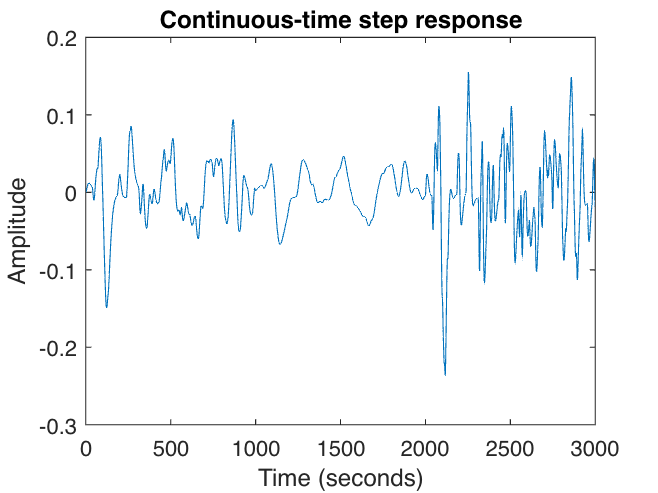

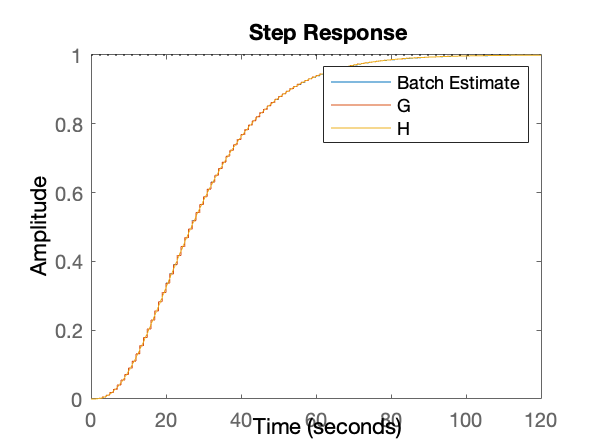

% Problem 4:
% Perform parameters tracking using different forgetting methods
% For each of the signals obtained before

% Linear
% Exponential
% Time Varying exponential
% Restricted
% Use of prior information

% With each of the signals obtained before

% Solution
a_old = a;
a_new = [1 1 1 1];
a = a_old;
u = UU;
n_samplesBatch = 30;
na = numel(a);
nb = numel(b);
n_samples = 1000;
[Y, ~, theta_batch, P] = ARXBatch(na,nb,n_samples,u,T);


sig = 0.1;
y = zeros(n_samples, 1);
y(5:n_samples) = Y;
theta = zeros(na + nb, n_samples);
theta(:, n_samplesBatch) = theta_batch;

f = @(z, a, b) a*z(1:na) + b*z(na+1:end) + sig*randn();
for i = (n_samplesBatch+1):n_samples
    if i > n_samples
        a = a_new;
    end
    % Regresor construction
    z = [-y(i - 1:-1:i-na); u(i:-1:i-nb + 1)];
    y(i) = f(z, a, b);
    
    

    % Zeta
    zeta = z'*P*z;
    
    % Prediction error
    epsilon = y(i) - z'*theta(:, i-1);
    
    % Kalman gain
    K = P*z/(1+zeta);
    
    %%  Filtering (Data) step:
    %   Mean value update
    theta(:,i) = theta(:,i-1) + K*epsilon;
    
    %   Covariance update
    P = P - P*z*z'*P/(1+zeta);
    
    P_data_step = P;
    
    %%  Propagation (Time) step:
    %   mean value parameter estimation does not change
    %       theta(t+1|t) = theta(t|t)
    %
    %   updating the covariance matrix
    
    %%%  No forgetting
    %     P = P;
    
    %%%  Linear forgetting
%         V = 0.000001*eye(na + nb);
%         P = P + V;
    
    %%%  Exponential forgetting
%         tef = 1500;
%         phi=1-1/tef;
%         P=1/phi*P;
    
    %%%  Restricted linear forgetting
%         K = P*z;
%         V = 0.0001*eye(numVariables);
%         zeta_v = z'*V*z;
%         Vo = K*(zeta_v/zeta^2)*K';
%         P = P + Vo;
    
    %%%  Restricted exponential forgetting
        K = P*z;
        tef = 250;
        fi=1-1/tef;
        zeta_v = (1-fi)/fi * zeta;
        Vo = K*(zeta_v/zeta^2)*K';
        P = P + Vo;
    
    P_time_step = P;
end


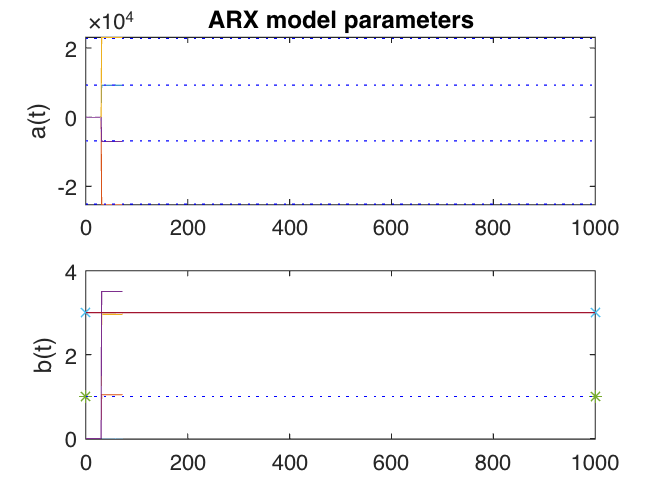


% Plots of the estimates and true values
figure(10)
subplot(2,1,1)
AA = theta(1:na,:);
plot(t,AA)
hold on
plot([0,time],[a(1,1),a(1,1)],'b:')
plot([0,time],[a(1,2),a(1,2)],'b:')
plot([0,time],[a(1,3),a(1,3)],'b:')
plot([0,time],[a(1,4),a(1,4)],'b:')
hold off
ylabel('a(t)')
title('ARX model parameters')

subplot(2,1,2)
BB = theta(na+1:end,:);
plot(t,BB)
hold on
plot([0,time],[b(1,1),b(1,1)],'b:')
plot([0,time],[b(1,2),b(1,2)],'b:')
plot([0,time],[b(1,3),b(1,3)],'b:')
plot([0,time],[b(1,4),b(1,4)],'b:')
hold off
ylabel('b(t)')


% Problem 5
% Conclusion
% Lessons learned

% Plan
% Describe how each forgetting method affects results of parameter
% estimation
% Describe how does each excitation signal has influence on results of
% parameter estimation


## Additional tools

% Storing figures
if storeFigures
    for i=1:8
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end


function [Y, Z, theta, P] = ARXBatch(na,nb,n_samples,u,T)
% You can enforce the estimated model structure with the arguments
% First argument sets the number of parameters in denominator of the TF
% Second argument sets the number of parameters in numerator of the TF




Ts = 1;
tau = 10;
time = numel(T);
% Continuous-time system
sys = tf(1,[tau^3 3*tau^2 3*tau 1]);
title("Continuous-time step response");

variance = 0.01;
b = [1 3 3 1];
a = [(8*tau^3+12*tau^2+6*tau+1) (-24*tau^3-12*tau^2+6*tau+3) (24*tau^3-12*tau^2-6*tau+3) (-8*tau^3+12*tau^2-6*tau+1)];
dsysARX = tf(b,a,Ts,'Variable','z^-1');
He = tf(1, a, Ts,'Variable','z^-1');  
y = lsim(dsysARX, u, T')+lsim(He,sqrt(variance)*randn(time,1),T');

G = dsysARX;
H = sys;
% Output vector
Y=y(1 + max(na,nb):n_samples);

% Regressor
Z=zeros(n_samples - max(na,nb),na+nb);

for i=1+max(na,nb):size(Z,1)+max(na,nb)
    % from 5 to 1000
    Z(i - max(na,nb),:)=[-y(i-1:-1:i-na); u(i:-1:i-nb+1)];
end


% Batch identification (least squares)
% theta_batch = pinv(Z)*Y
% badly conditioned formula
theta_batch = (Z'*Z)\Z'*Y;
P_batch = inv(Z'*Z);
% QR algorithm solution
[Q,R] = qr(Z);
theta_batch = R\Q'*Y;
P_batch = inv(R'*R);

theta = theta_batch;
P = P_batch;
% Plot result
G_batch = tf(theta_batch(na+1:end)',[1 theta_batch(1:na)'],Ts,'Variable','z^-1');
G_batch.Name = 'Batch Estimate';
figure;
step(G_batch)
hold on;
step(G)
step(H)
legend show
fix_ylim = ylim;
end
